# PBL Height Calculation 

% Import Data File
fid = fopen('/Users/Jaxen/Desktop/2019 Eclipse/Practice_Launches/W3_L1_1754_052319_MREDI.txt');

data = textscan(fid,'%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f%f', 'HeaderLines',20, 'CollectOutput',true);
fclose(fid);
thedata = data{1};
L = length(thedata)

L = 5896

#### Get Data from File

% Pull data
temp = zeros(L,1);
alt = zeros(L,1);
p = zeros(L,1);
h = zeros(L,1);
w = zeros(L,1);
th = zeros(L,1);

for i = 1:L
    %Column vectors
    temp(i) = thedata(i,3)+273; %Kelvin
    alt(i) = thedata(i,9); %meters
    p(i) = thedata(i,2); %hPa
    h(i) = thedata(i,4)*0.01; %unitless
    w(i) = thedata(i,5); %m/s
    th(i) = thedata(i,6); %degrees
end

tempc = temp-273;
height = alt-alt(1);

# Calculate Richardson Number (Ri Method)

% Calculations
eps = 0.622;

%saturation vapor pressure
es = 6.1121*exp((18.678-(tempc/234.84)).*(tempc./(257.14+tempc))); %hPa

%vapor pressure
e = es.*h; %hPa

%water vapor mixing ratio
rv = (0.622*e)./(p-e); %unitless

%potential temperature
pt = (1000.0^0.286)*temp./(p.^0.286); %kelvin

%virtual potential temperature
vpt = pt.*((1+(rv./eps))./(1+rv)); %kelvin

%component wid speeds, m/s
u = w.*cos(pi*th/180.0); 
v = w.*sin(pi*th/180.0);

vpt0 = vpt(1);
alt0 = alt(1);

%richardson number 
ri = (((vpt-vpt0)./vpt0).*(alt-alt0)*9.8)./((u).^2+(v).^2);

mins = abs(ri-0.25);
minn = find(mins == min(mins))

minn = 4

PBLri = height(minn)

PBLri = 22

#### Ri Method Plots

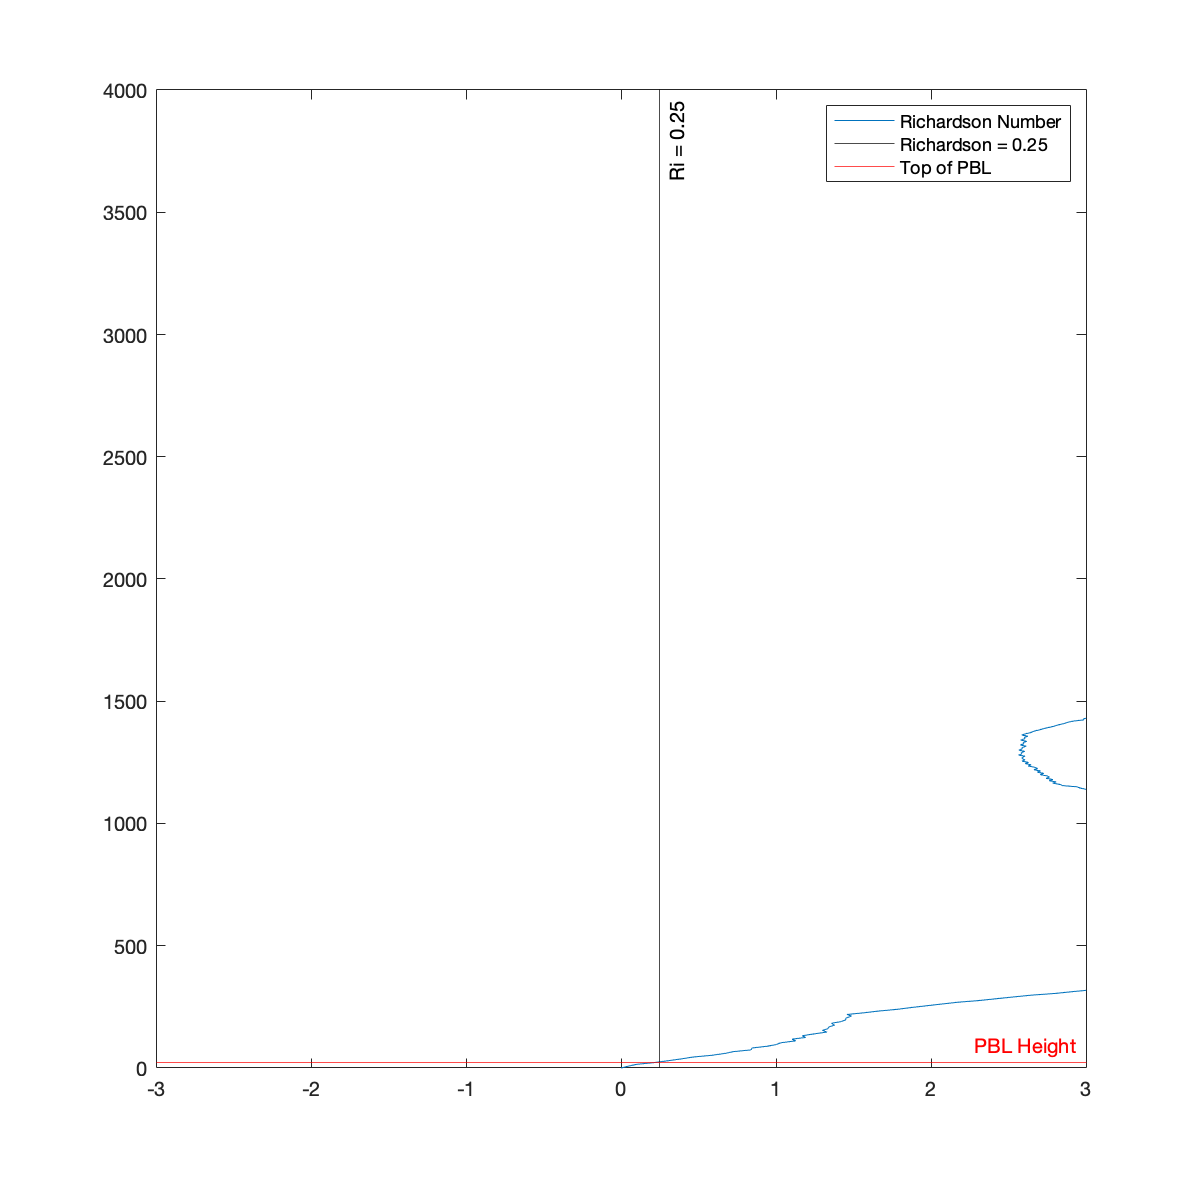

%Plot and find PBL Height
figure('Position',[10 10 600 600])

% PBL = interp1(ri,alt-alt0, 0.25, 'linear') %find pbl height

plot(ri,alt-alt0,'DisplayName', 'Richardson Number') %plot richardson number
hold on
x1 = xline(0.25, 'k',{'Ri = 0.25'}, 'DisplayName','Richardson = 0.25'); %where richardson number = 0.25
y2 = yline(PBLri,'r',{'PBL Height'}, 'DisplayName','Top of PBL'); %height of pbl
hold off
x1.LabelHorizontalAlignment = 'right';
y2.LabelHorizontalAlignment = 'right';
legend('show');
axis([-3, 3, 0, 4000])

# Potential Temperature Method

vptc = vpt-273;
ptc = pt-273;
ptc0 = ptc(1);
dp = deriv(ptc, alt-alt0);
ptc;

#### Find Max Derivative of Pot Temp

smth = smoothdata(dp,'movmedian',2);

% plot(smth, alt-alt0)
% axis([-0.4, 0.4, 0, 3000])

A = find(height > 50);
B = find(height < 4000);
C = intersect(A,B);
dph = zeros([length(height) 1]);

for i = C(1):C(end)
    dph(i) = smth(i);
end

locate = find(dph == max(dph));
PBLPT = height(locate(1))

PBLPT = 2777

#### Plot Potential Temp Method

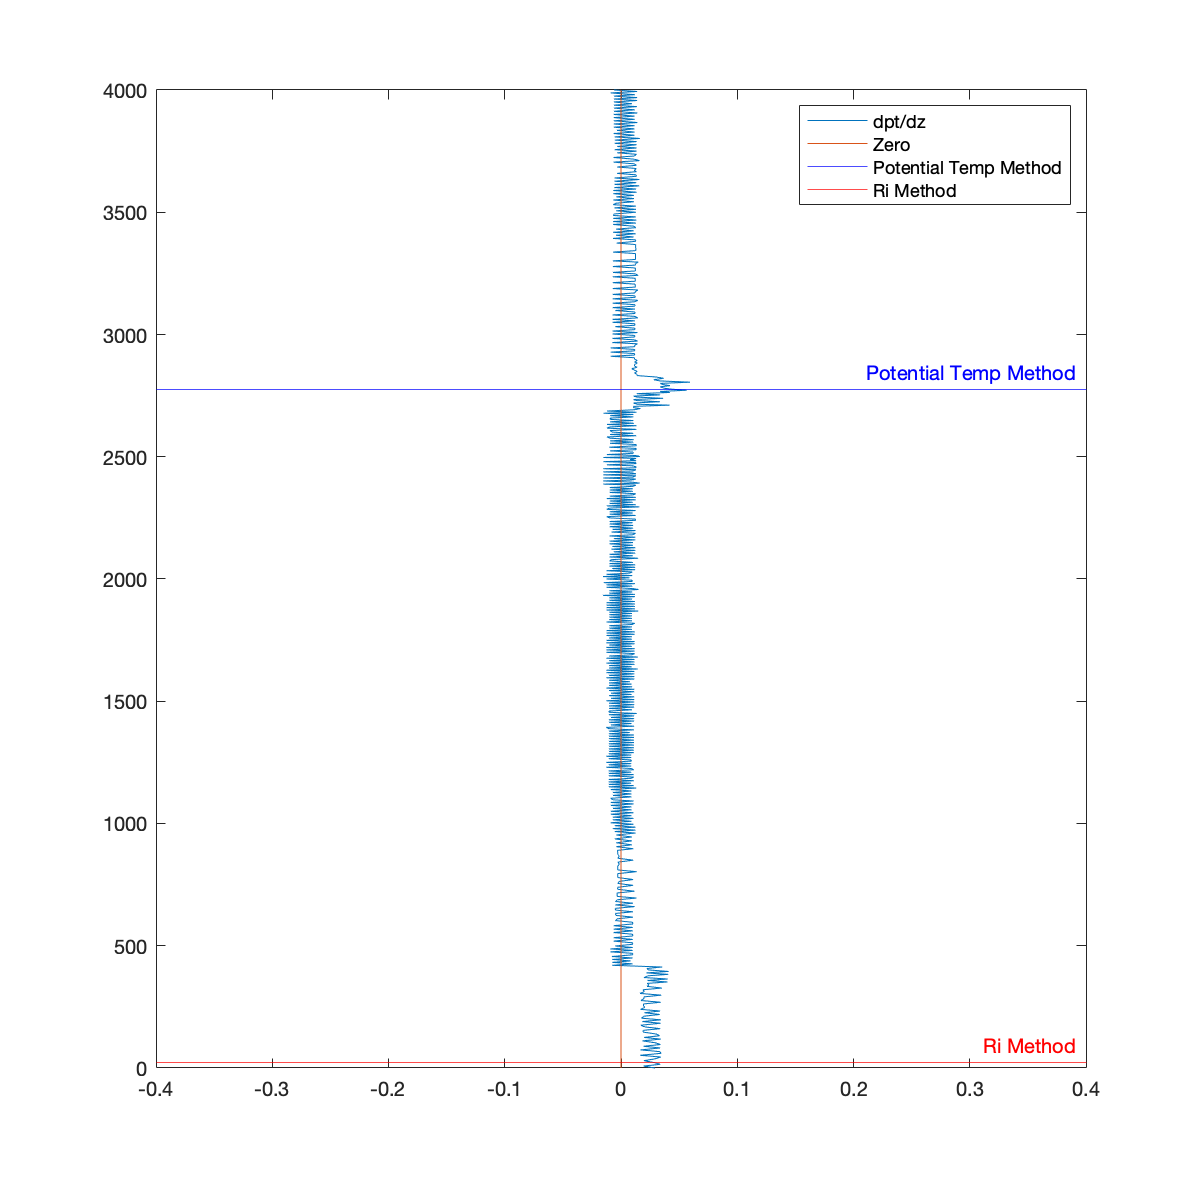

%Plot Potential Temp Method
zero = zeros([length(alt) 1]);
plot(dp, alt-alt0, 'DisplayName','dpt/dz')
hold on 
plot(zero,alt-alt0, 'DisplayName','Zero')
y3 = yline(PBLPT,'b',{'Potential Temp Method'},'DisplayName','Potential Temp Method');
y4 = yline(PBLri,'r', {'Ri Method'},'DisplayName','Ri Method');
hold off
y3.LabelHorizontalAlignment = 'right';
y4.LabelHorizontalAlignment = 'right';
legend('show');
axis([-0.4, 0.4, 0, 4000])

#### Plot Potential Temp with PBL Heights

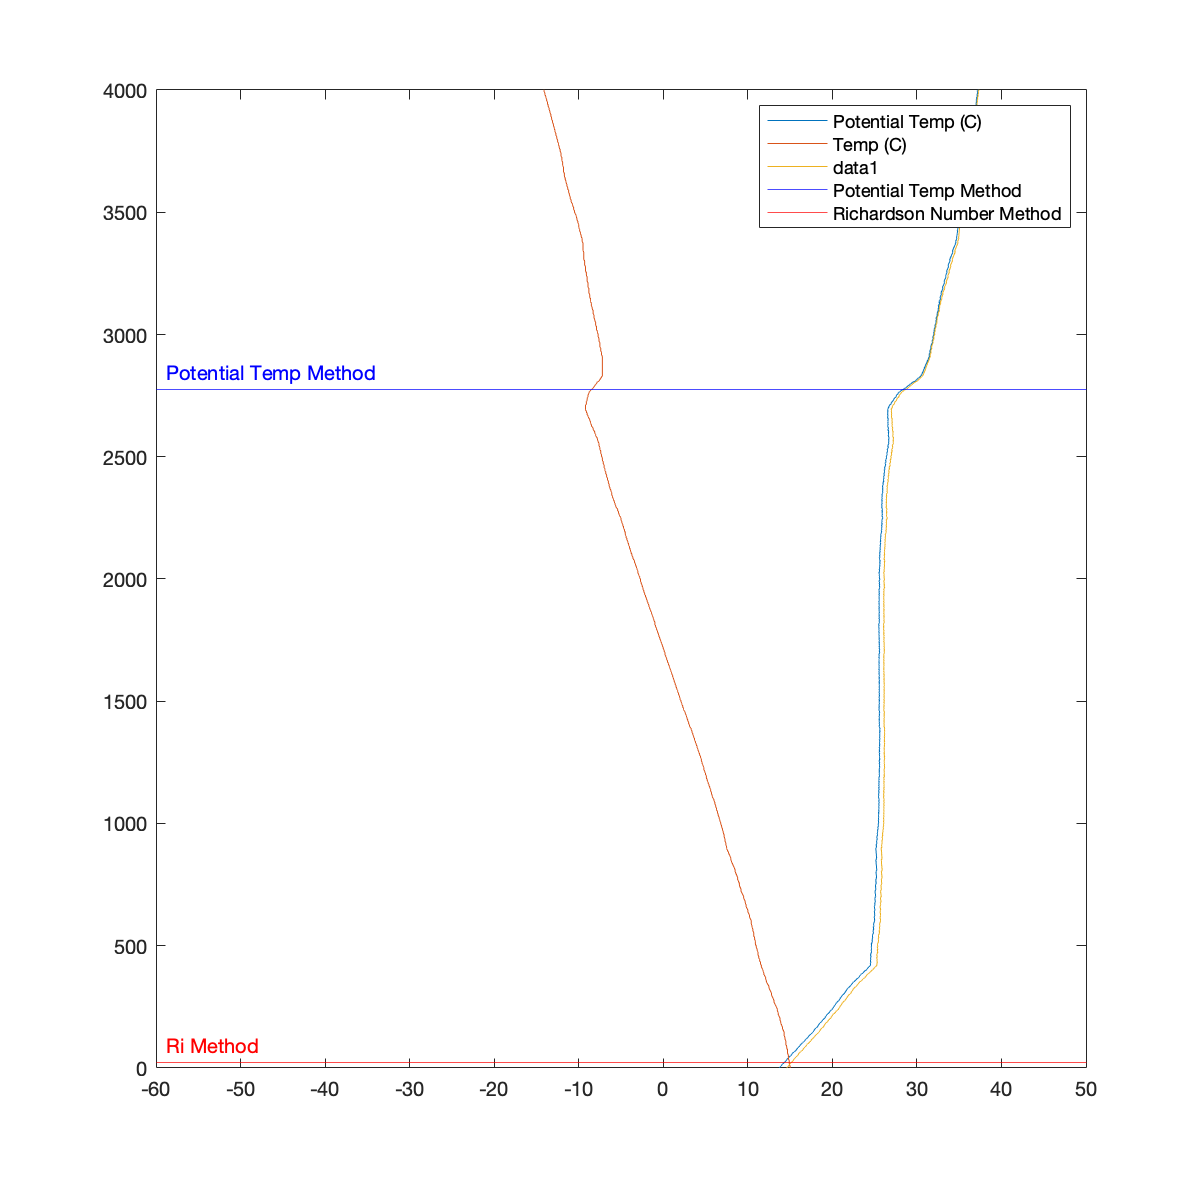

plot(ptc, alt-alt0, 'DisplayName','Potential Temp (C)')
hold on
plot(tempc, alt-alt0, 'DisplayName','Temp (C)')
plot(vptc,alt-alt0)
y5 = yline(PBLPT,'b',{'Potential Temp Method'}, 'DisplayName','Potential Temp Method');
y8 = yline(PBLri, 'r', {'Ri Method'}, 'DisplayName', 'Richardson Number Method'); %height of pbl
hold off
y5.LabelHorizontalAlignment = 'left';
y8.LabelHorizontalAlignment = 'left';
legend('show');
axis([-60,50 , 0, 4000])

# Specific Humidity Method

%specific humidity
q = rv./(1+rv);
dq = deriv(q,alt-alt0);
dq1 = smoothdata(gradient(q,alt-alt0));

dqh = zeros([length(height) 1]);

for i= C(1):C(end)
    dqh(i) = dq1(i);
end 

locate = find(dqh == min(dqh));
PBLQ = height(locate)

PBLQ = 2744

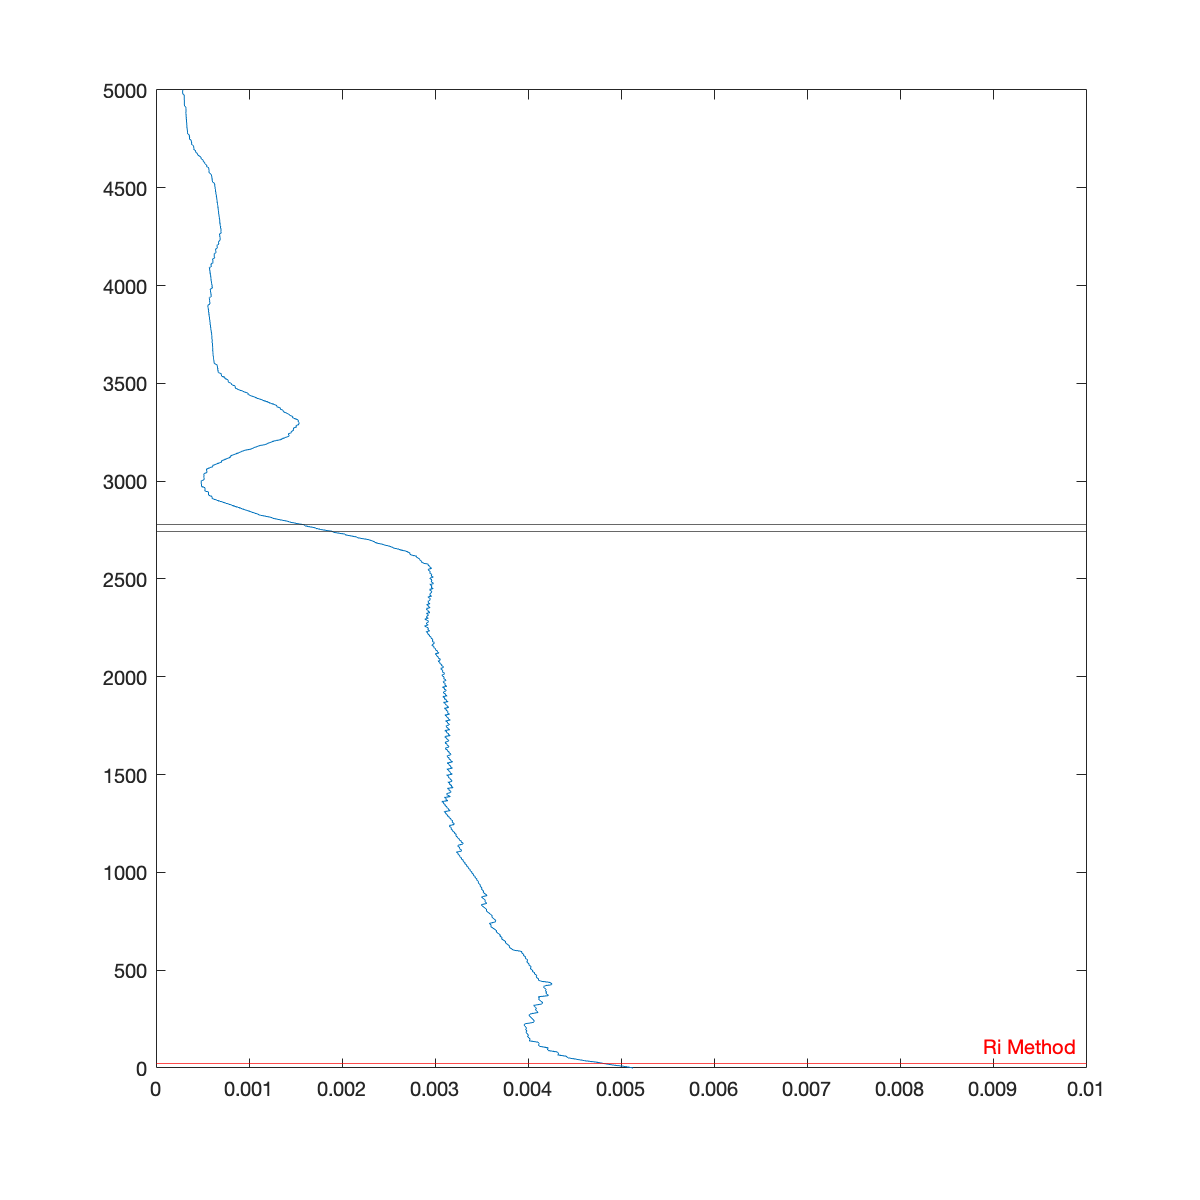

plot(q,alt-alt0)
hold on 
yline(PBLQ);
yline(PBLPT);
yline(PBLri,'r', {'Ri Method'},'DisplayName','Ri Method');
hold off
axis([0,0.01,0,5000])

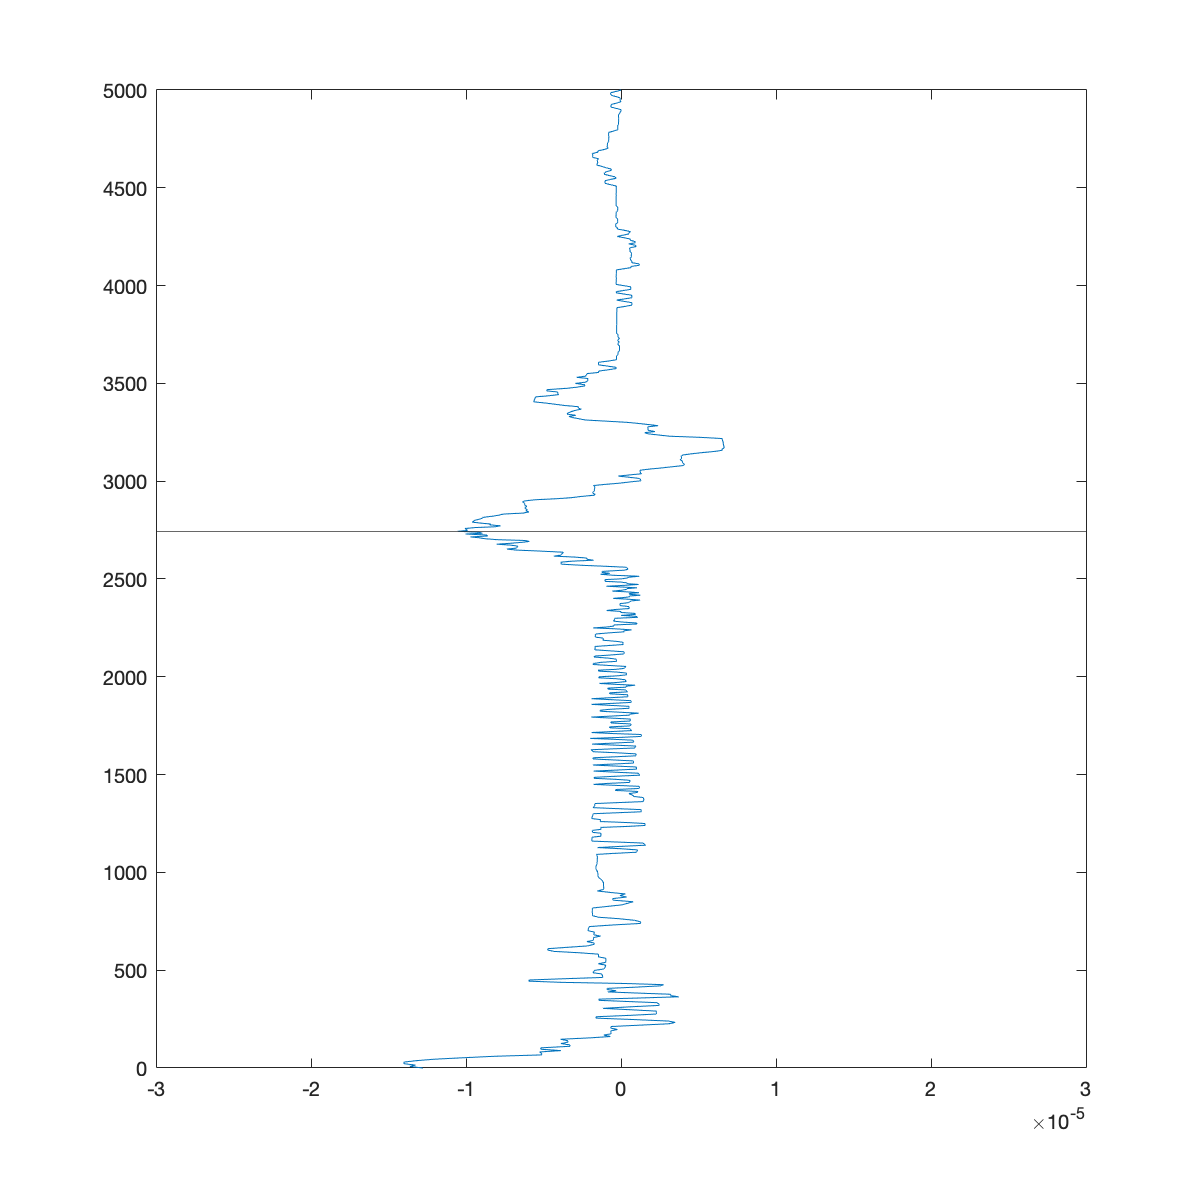

plot(dq1, alt-alt0)
hold on
yline(PBLQ);
hold off
axis([-0.00003,0.00003,0,5000])

(PBLri+PBLPT+PBLQ)/3

ans = 1.8477e+03

ans = 1

#### Plot Wind Speed with PBL Heights

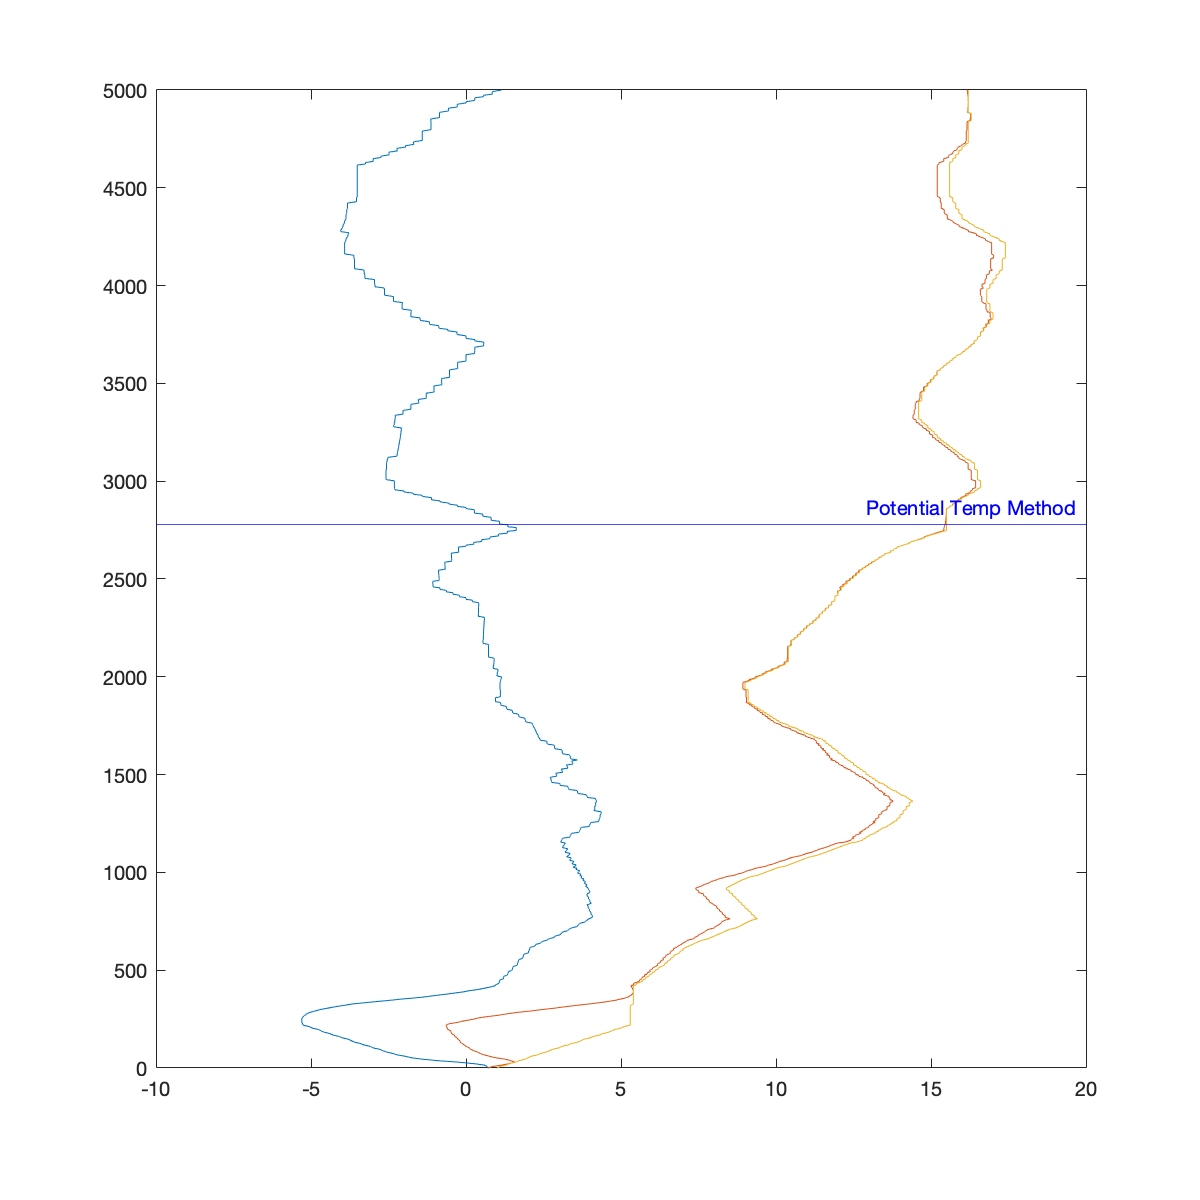

plot(u,alt-alt0,'DisplayName','u component') %plot wind speed
hold on
plot(v,alt-alt0, 'DisplayName','v component')
plot(w,alt-alt0,'DisplayName','Wind Speed')
y7 = yline(PBLPT,'b',{'Potential Temp Method'}, 'DisplayName','Potential Temp Method');
% y8 = yline(PBL, 'r', {'Ri Method'}, 'DisplayName', 'Richardson Number Method');
hold off
y7.LabelHorizontalAlignment = 'right';
% y8.LabelHorizontalAlignment = 'right';
% legend('show');
axis([-10, 20, 0, 5000])

#### Functions

function y = deriv(a,b)
y = zeros([length(a) 1]);
    for i=1:length(a)-1
       x = (a(i+1)-a(i))/(b(i+1)-b(i));
       y(i) = x;
    end
end